## Proyecto: Control de circuito RC

###  **Función de transferencia del modelo de la planta**

Planta `P`

s=tf('s');

% Valores experimentales
R1 = 9.960*10^(3);
R2 = 9.860*10^(3);
C1 = 94.5*10^(-6);
C2 = 94.7*10^(-6);

% Función de transferencia de lazo abierto
P=1/(R1*R2*C1*C2*s^2 + (R1*C1 + R1*C2 + R2*C2)*s + 1)


P =
 
             1
  ------------------------
  0.8789 s^2 + 2.818 s + 1
 
Continuous-time transfer function.


### Diagrama de Bode de lazo abierto

fig = figure

fig =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [272 158 560 337.2514]
       Units: 'pixels'

  Show all properties


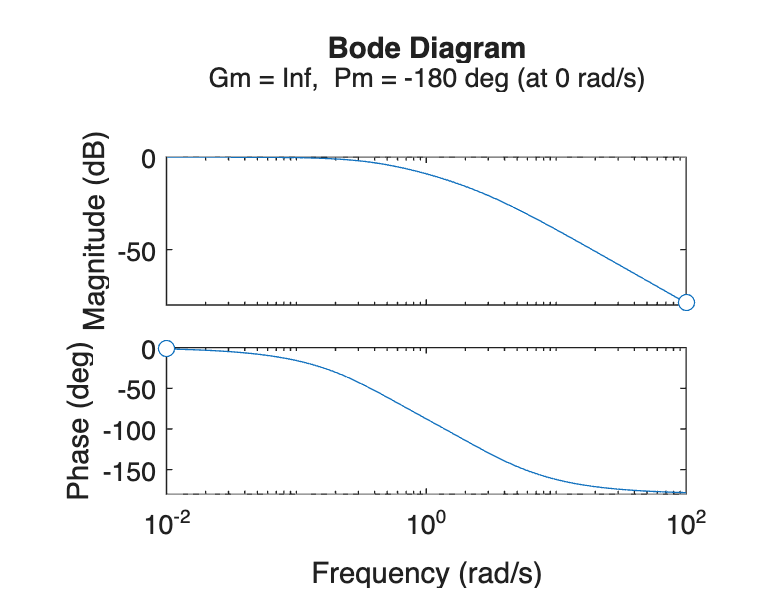

margin(P);

% Exportar svg
set(fig, 'Units', 'inches');
fig.Position(3:4) = [5 4]; % Ancho = 5 in, alto = 4 in
exportgraphics(fig, 'bode_lazo_abierto.svg', 'ContentType', 'vector');

### Respuesta temporal de lazo abierto

% Tiempo
t = 0:0.001:20;

% Función escalón unitario
r = 1 * heaviside(t);

% Simular el sistema de lazo abierto
y = lsim(P, r, t);

% Graficar
fig = figure

fig =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [272 158 560 337.2514]
       Units: 'pixels'

  Show all properties


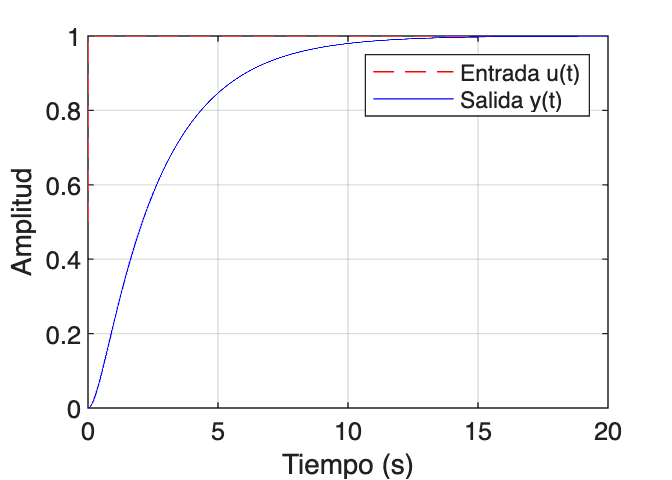

plot(t, r, 'r--', t, y, 'b')
xlabel('Tiempo (s)');
ylabel('Amplitud');
% title('Respuesta de lazo abierto');
legend('Entrada u(t)', 'Salida y(t)');
grid on;

% Exportar svg
set(fig, 'Units', 'inches');
fig.Position(3:4) = [3.5 2.5]; % Ancho = 3.5 in, alto = 2.5 in
exportgraphics(fig, 'respuesta_lazo_abierto.svg', 'ContentType', 'vector');

### `Sisotool`

sisotool(P);

### Conversión de continuo a analógico

% Convertir controlador a discreto
t_muestreo = 0.1;

Cz = c2d(C, t_muestreo, 'zoh')


Cz =
 
  1.5996 (z-0.9594)
  -----------------
        (z-1)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.


### `Respuesta temporal continua de lazo cerrado`

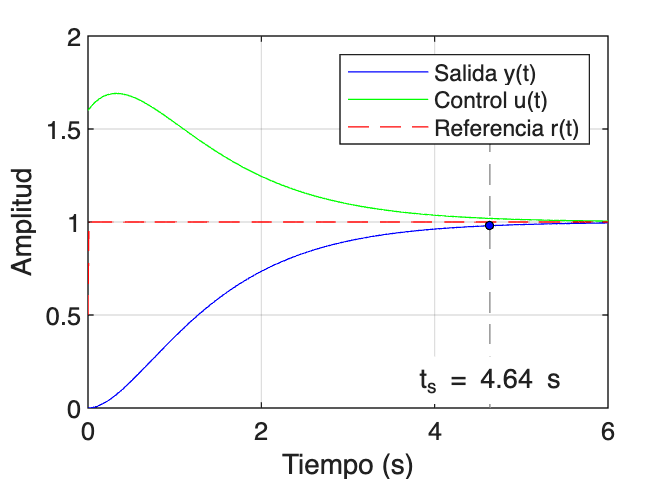

% Tiempo
t = 0:0.01:6;

% Función escalón unitario
r = 1 * heaviside(t);

% Exportado de Sisotool
[y, t1] = step(IOTransfer_r2y, t); % Salida y
[u, t2] = step(IOTransfer_r2u, t); % Señal de control u

fig = figure;
plot(t1, y, 'b');
hold on;
plot(t2, u, 'g');
plot(t, r, 'r--');

xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Salida y(t)', 'Control u(t)', 'Referencia r(t)');
grid on;

% Exportado de Sisotool
ts = tiempo_asentamiento.Position(1);
ys = tiempo_asentamiento.Position(2);
plot([ts ts], ylim, '--', 'Color', [0.5 0.5 0.5], 'HandleVisibility', 'off');

text(ts, min(ylim) + 0.05, ...
     sprintf('t_s = %.2f s', ts), ...
     'VerticalAlignment', 'bottom', ...
     'HorizontalAlignment', 'center', ...
     'FontSize', 10, ...
     'BackgroundColor', 'white', ...
     'Margin', 2);

% Marcador sobre la curva
plot(ts, ys, 'ko', 'MarkerFaceColor', 'b', 'MarkerSize', 3, 'HandleVisibility', 'off');
hold off;

% Exportar svg
set(fig, 'Units', 'inches');
fig.Position(3:4) = [3.5 2.5]; % Ancho = 3.5 in, alto = 2.5 in
exportgraphics(fig, 'respuesta_continua.svg', 'ContentType', 'vector');

### Respuesta temporal discreta de lazo cerrado

fig = figure

fig =   Figure (38) with properties:

      Number: 38
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [272 158 560 337.2514]
       Units: 'pixels'

  Show all properties


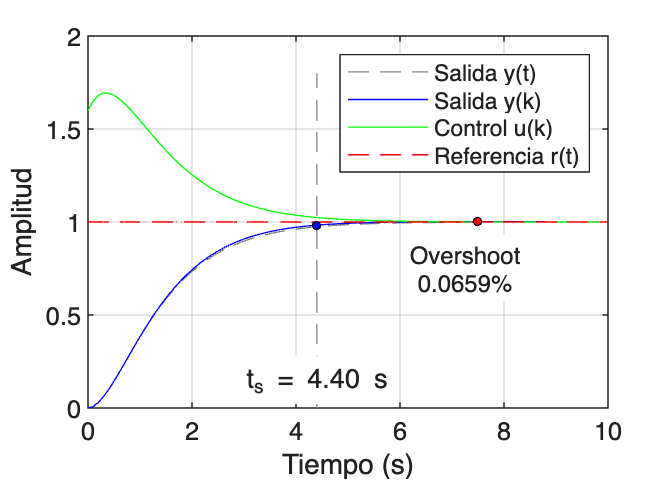


% Datos exportados de Simulink
plot(out.y.Time, out.y.Data, '--', 'Color', [0.5, 0.5, 0.5]);
hold on;
plot(out.yz.Time, out.yz.Data, 'b');
plot(out.uz.Time, out.uz.Data, 'g');
plot(out.r.Time, out.r.Data, 'r--');

% Extraer datos de la señal yz
yz_y = out.yz.Data;
yz_t = out.yz.Time;

% Calcular el valor final y la tolerancia del 2%
yz_final = yz_y(end);
yz_tol = 0.02 * abs(yz_final);

% Determinar los puntos dentro de la banda de 2%
yz_within_bounds = abs(yz_y - yz_final) <= yz_tol;

% Encontrar el tiempo de asentamiento
for k = 1:length(yz_within_bounds)
    if all(yz_within_bounds(k:end))
        yz_ts = yz_t(k);
        break;
    end
end

% Calcular sobrepaso máximo respecto al valor final
[yz_max, idx_max] = max(yz_y);
yz_tmax = yz_t(idx_max);
yz_overshoot = ((yz_max - yz_final) / abs(yz_final)) * 100;

% Indicar tiempo de asentamiento al 2%
plot([yz_ts yz_ts], ylim, '--', 'Color', [0.5 0.5 0.5], 'HandleVisibility', 'off');
plot(yz_ts, yz_y(find(yz_t == yz_ts, 1)), 'ko', 'MarkerFaceColor', 'b', 'MarkerSize', 3);
text(yz_ts, min(ylim) + 0.05, ...
     sprintf('t_s = %.2f s', yz_ts), ...
     'VerticalAlignment', 'bottom', ...
     'HorizontalAlignment', 'center', ...
     'FontSize', 10, ...
     'BackgroundColor', 'white', ...
     'Margin', 2);

% Graficar el punto máximo
plot(yz_tmax, yz_max, 'ko', 'MarkerFaceColor', 'r', 'MarkerSize', 3);
text(yz_tmax-0.25, yz_max-0.25, ...
    sprintf('Overshoot\n%.4f%%', yz_overshoot), ...
    'HorizontalAlignment', 'center', ...
    'FontSize', 9, ...
    'BackgroundColor', 'white', ...
    'Margin', 2);

hold off;

% Labels y leyenda
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Salida y(t)', 'Salida y(k)', 'Control u(k)', 'Referencia r(t)');
grid on;

% Exportar svg

set(fig, 'Units', 'inches');
fig.Position(3:4) = [3.5 2.5]; % Ancho = 3.5 in, alto = 2.5 in
exportgraphics(fig, 'respuesta_discreta.svg', 'ContentType', 'vector');

### Señal cuadrada en el tiempo

fig = figure

fig =   Figure (63) with properties:

      Number: 63
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [272 158 560 337.2514]
       Units: 'pixels'

  Show all properties


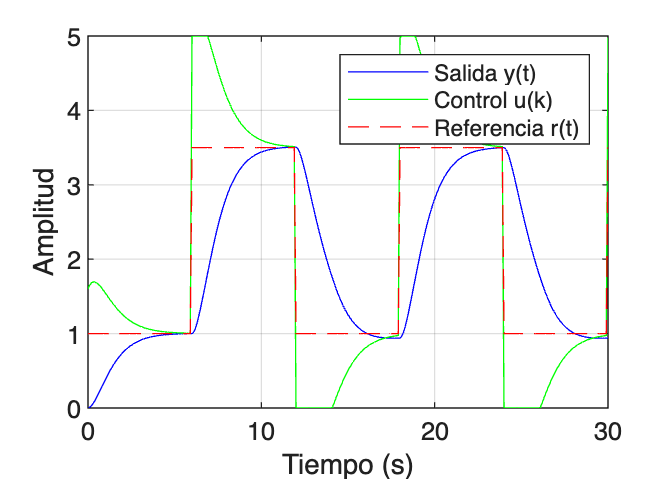


% Exportado de Simulink
plot(out.yz_sq.Time, out.yz_sq.Data, 'b');
hold on;
plot(out.uz_sq.Time, out.uz_sq.Data, 'g');
plot(out.r_sq.Time, out.r_sq.Data, 'r--');
hold off;

% Labels y leyenda
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Salida y(t)', 'Control u(k)', 'Referencia r(t)');
grid on;

% Exportar svg
set(fig, 'Units', 'inches');
fig.Position(3:4) = [3.5 2.5]; % Ancho = 3.5 in, alto = 2.5 in
exportgraphics(fig, 'sim_senal_cuadrada.svg', 'ContentType', 'vector');

### Diagrama de Bode de lazo cerrado

fig = figure

fig =   Figure (32) with properties:

      Number: 32
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [272 158 560 337.2514]
       Units: 'pixels'

  Show all properties


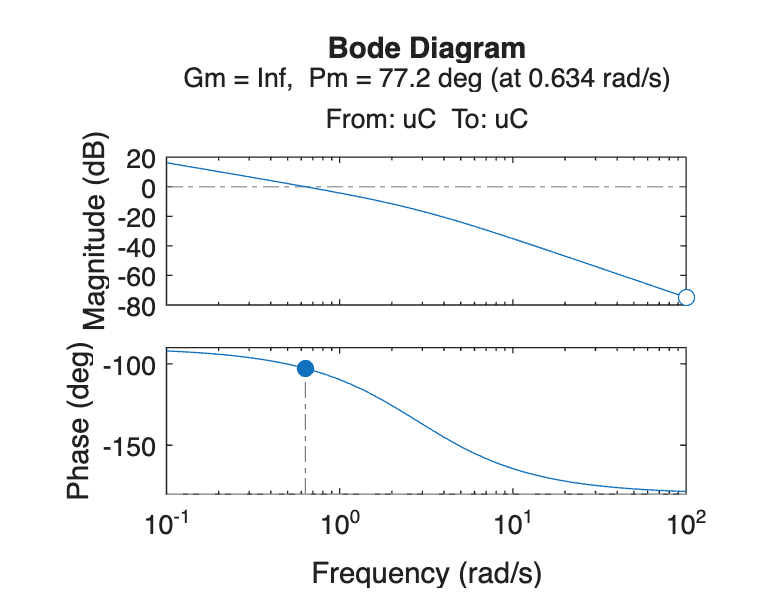

% Exportado de Sisotool
margin(LoopTransfer_C);

% Exportar svg
set(fig, 'Units', 'inches');
fig.Position(3:4) = [5 4]; % Ancho = 5 in, alto = 4 in
exportgraphics(fig, 'bode_lazo_cerrado.svg', 'ContentType', 'vector');

### LGR de lazo cerrado

fig = figure

fig =   Figure (53) with properties:

      Number: 53
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [272 158 560 337.2514]
       Units: 'pixels'

  Show all properties


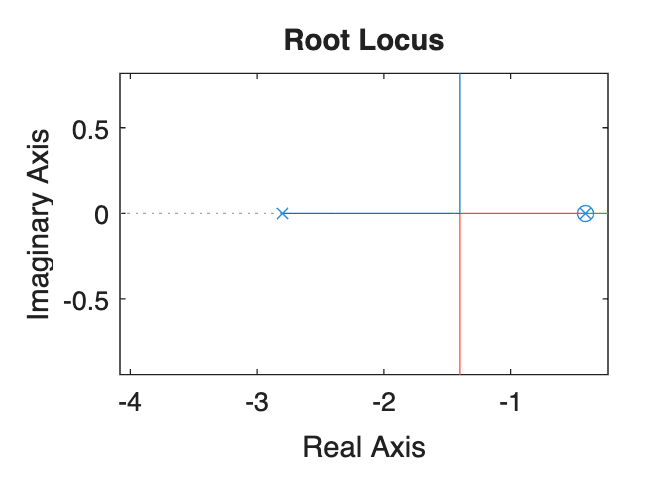

% Exportado de Sisotool
rlocus(LoopTransfer_C);

% Exportar svg
set(fig, 'Units', 'inches');
fig.Position(3:4) = [3.5 2.5]; % Ancho = 3.5 in, alto = 2.5 in
exportgraphics(fig, 'rlocus.svg', 'ContentType', 'vector');

### Datos experimentales

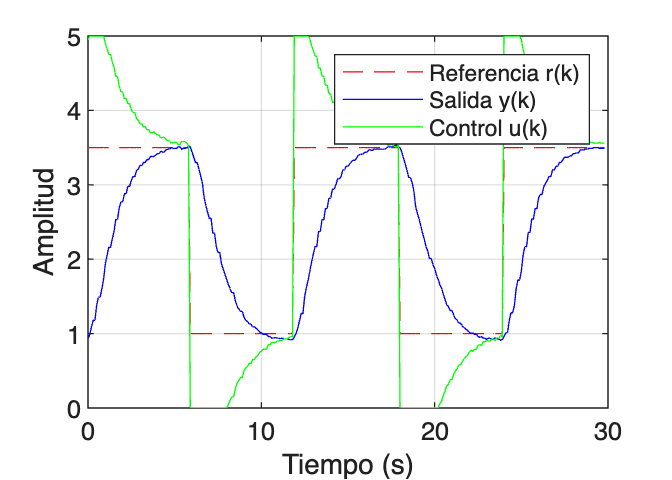

% Leer los datos del archivo CSV
datos_exp = readtable('datos_senal_cuadrada.csv');

% Extraer las columnas
t_exp = datos_exp.t;
r_exp = datos_exp.r;
y_exp = datos_exp.y;
u_exp = datos_exp.u;

% Graficar
fig = figure;
plot(t_exp, r_exp, 'r--');
hold on;
plot(t_exp, y_exp, 'b');
plot(t_exp, u_exp, 'g');
hold off;

% Etiquetas
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Referencia r(k)', 'Salida y(k)', 'Control u(k)');
grid on;

% Exportar svg
set(fig, 'Units', 'inches');
fig.Position(3:4) = [3.5 2.5]; % Ancho = 3.5 in, alto = 2.5 in
exportgraphics(fig, 'exp_senal_cuadrada.svg', 'ContentType', 'vector');